%--------------------------------------------------------------------------
%   
%          ADJUSTMENT THEORY I
%    Exercise 9: Adjustment Calculation - part IV  
% 
%   Author         : Anastasia Pasioti
%   Version        : October 11, 2018
%   Last changes   : January 11, 2023
%
%--------------------------------------------------------------------------

clc;
clear all;
close all;

%--------------------------------------------------------------------------
%   Task 1
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------
%   Observations and initial values for the unknowns
%--------------------------------------------------------------------------
%Load data
data = load('Exercise9Task1.txt');

%Error-free values
t = data(:,1);
y = data(:,2);

%Vector of observations
L =  y;

%Number of observations
no_n = length(L); 

%Initial values for the unknowns
a=3;
f=1/3;
phi=0;
c=0;

%Vector of initial values for the unknowns
X_0 = [a; f; phi; c];

%Number of unknowns
no_u = length(X_0);

%Redundancy
r =  no_n -no_u;

%--------------------------------------------------------------------------
%  Stochastic model
%--------------------------------------------------------------------------
s_y = 0.15;        %[m]

%VC Matrix of the observations
S_LL = s_y^2*eye(no_n);

%Theoretical standard deviation
sigma_0 = 1;     %a priori

%Cofactor matrix of the observations
Q_LL = 1/sigma_0^2*S_LL;

%Weight matrix
P = inv(Q_LL);

%--------------------------------------------------------------------------
%  Adjustment
%--------------------------------------------------------------------------
%break-off conditions
epsilon = 10^-15;
delta = 10^-15;
max_x_hat = Inf; 
Check2 = Inf;

%Number of iterations
iteration = 0;

while  max_x_hat>epsilon || Check2>delta
    
     %Observations as functions of the approximations for the unknowns
     L_0 = a*sin(2*pi*f*t+phi)+c;
     
     %Vector of reduced observations
     l = L-L_0;
    
     %Design matrix with the elements from the Jacobian matrix J
     A = [sin(2*pi*f*t+phi) 2*pi*a*t.*cos(2*pi*f*t+phi) a*cos(2*pi*f*t+phi) ones(no_n,1)];   
    
     %Normal matrix
     N = A'*P*A;
     
     %Vector of right hand side of normal equations
     n = A'*P*l;
    
     %Inversion of normal matrix / Cofactor matrix of the unknowns
     Q_xx = inv(N);
    
     %Solution of the normal equations
     x_hat = Q_xx*n;
       
     %Update
     X_hat = X_0+x_hat;
     X_0=X_hat;

     a=X_hat(1);
     f=X_hat(2);
     phi=X_hat(3);
     c=X_hat(4);

    
     %Check 1
     max_x_hat=max(abs(x_hat));
     
     %Vector of residuals
     v = A*x_hat-l; %small L and not 1
 
     %Vector of adjusted observations
     L_hat = L+v;
    
     %Objective function
     vTPv = v'*P*v;
    
     %Functional relationships without the observations
     Psi= a*sin(2*pi*f*t+phi)+c;

     %Check 2
     Check2 = max(abs(L_hat-Psi));
    
     %Update number of iterations
     iteration = iteration+1;
 
end

if Check2<=delta
    disp('Everything is fine!')
else
    disp('Something is wrong.')
end

Everything is fine!


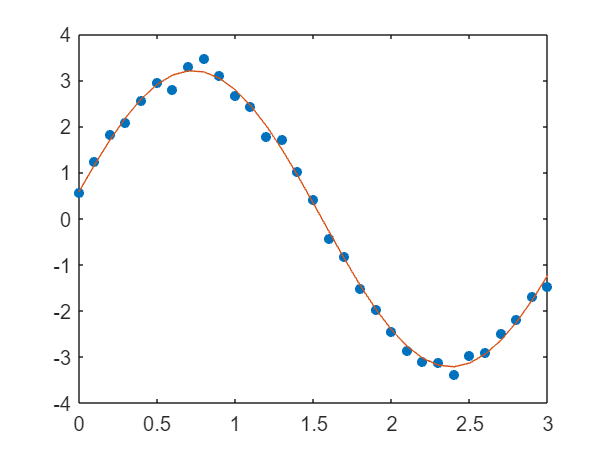


%Empirical reference standard deviation
s_0 = sqrt(vTPv/r);

%VC matrix of adjusted unknowns
S_XX_hat = s_0^2*Q_xx;

%Standard deviation of the adjusted unknowns
s_X = sqrt(diag(S_XX_hat));

%Cofactor matrix of adjusted observations
Q_LL_hat = A*Q_xx*A';

%VC matrix of adjusted observations
S_LL_hat = s_0^2*Q_LL_hat;

%Standard deviation of the adjusted observations
s_L_hat = sqrt(diag(S_LL_hat));

%Cofactor matrix of the residuals
Q_vv = Q_LL-Q_LL_hat;

%VC matrix of residuals
S_vv = s_0^2*Q_vv;

%Standard deviation of the residuals
s_v = sqrt(diag(S_vv));

%--------------------------------------------------------------------------
%  Plot
%--------------------------------------------------------------------------
plot(t,y,'.',Markersize=15)
hold on
plot(t, a*sin(2*pi*f*t+phi)+c)


[X_hat s_X]

ans =           3.21223792589513        0.0368936753710237
         0.302979973960894       0.00214191956388086
         0.183336646240886        0.0226611749262116
       -0.0047956284721518        0.0260400157054528
